Definicja ukladu ciągłego:

% state-space
A = [-1, 5 1; 0, -2, 1; 0, 0, -1];
B = [0; 0; 1];
C = [1, 0, 0];
sys = ss(A, B, C, 0)


sys =
 
  A = 
       x1  x2  x3
   x1  -1   5   1
   x2   0  -2   1
   x3   0   0  -1
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


% transmitancja
[num, den] = ss2tf(A, B, C, 0);
G = tf(num, den)


G =
 
          s + 7
  ---------------------
  s^3 + 4 s^2 + 5 s + 2
 
Continuous-time transfer function.
Model Properties


Dyskretyzacja modelu w przestrzeni stanów i transmitancji:

T = 0.83;

% state-space
sys_d = c2d(sys, T, 'tustin')


sys_d =
 
  A = 
           x1      x2      x3
   x1  0.4134   1.603  0.8846
   x2       0  0.0929  0.3205
   x3       0       0  0.4134
 
  B = 
           u1
   x1  0.3671
   x2   0.133
   x3  0.5866
 
  C = 
           x1      x2      x3
   y1  0.7067  0.8013  0.4423
 
  D = 
           u1
   y1  0.1835
 
Sample time: 0.83 seconds
Discrete-time state-space model.


% transmitancja
G_d = c2d(G, T, 'tustin')


G_d =
 
  0.1835 z^3 + 0.4566 z^2 + 0.3626 z + 0.08954
  --------------------------------------------
     z^3 - 0.9198 z^2 + 0.2477 z - 0.01588
 
Sample time: 0.83 seconds
Discrete-time transfer function.
Model Properties


Sprawdzenie stabilności wersji dyskretnej:

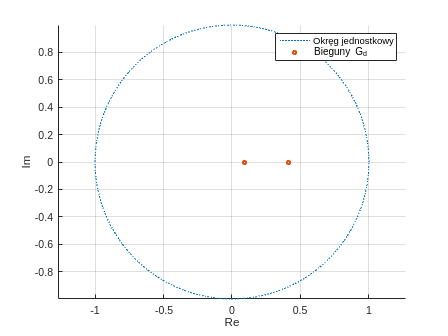

den = G_d.Denominator{1};
poles = roots(den);

figure();
grid on;
hold on;
xlabel("Re");
ylabel("Im");
axis equal;
legend("show");

theta = 0:0.01:2*pi;
plot(cos(theta), sin(theta), ":", "DisplayName", "Okręg jednostkowy");
plot(real(poles), imag(poles), "o", "LineWidth", 2, "MarkerSize", 3, "DisplayName", "Bieguny G_d")

Wyznaczenie macierzy układu zamkniętego z regulatorem proporcjonalnym $u=\mathrm{Kx}$

syms K real positive 
syms lambda 

Adz = simplify(sys_d.A - sys_d.B * K * sys_d.C);
cp = charpoly(Adz, lambda);

cp_col = collect(cp, lambda);
[coeffs_cp, powers] = coeffs(cp_col, lambda);

a3 = coeffs_cp(powers == lambda^3);
a2 = coeffs_cp(powers == lambda^2);
a1 = coeffs_cp(powers == lambda);
a0 = coeffs_cp(powers == 1);

S1 = [ ...
    a3, a2, a1; ...
     0, a3, a2; ...
     0,  0, a3 ...
];
S2 = [ ...
    a0, a1, a2; ...
     0, a0, a1; ...
     0,  0, a0; ...
];
P = S1'*S1 - S2'*S2;

p_delta = simplify([det(P(1,1)); det(P(1:2,1:2)); det(P(1:3,1:3)); det(P)]);
stable_k = solve(p_delta > 0, K, ReturnConditions=true)

stable_k = struct with fields:
             K: [2×1 sym]
    parameters: x
    conditions: [2×1 sym]


cond_1 = simplify(stable_k.conditions(1));
cond_2 = simplify(stable_k.conditions(2));

ineq_1 = children(cond_1);
ineq_2 = children(cond_2);

upper_1 = rhs(vpa(ineq_1(1), 10));
lower_1 = lhs(vpa(ineq_1(2), 10));
upper_2 = rhs(vpa(ineq_2(1), 10));
lower_2 = lhs(vpa(ineq_2(2), 10));

fprintf("x ∈ (%.4f, %.4f)\n", min([lower_1, lower_2]), min([upper_1, upper_2]));

x ∈ (0.0000, 2.8554)


Wartości własne ukłdau zamkniętego dla zakresu stabilnych $K$:

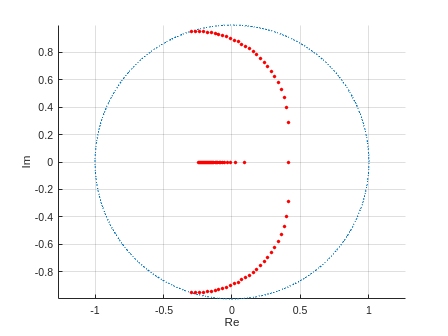

figure();
grid on;
hold on;
xlabel("Re");
ylabel("Im");
axis equal;

theta = 0:0.01:2*pi;
plot(cos(theta), sin(theta), ":", "DisplayName", "Okręg jednostkowy");

for k = min([lower_1, lower_2]):0.1:min([upper_1, upper_2])
    poles = eig(sys_d.A - sys_d.B * k * sys_d.C);
    plot(real(poles), imag(poles), "r.", "LineWidth", 4, "MarkerSize", 10);
end